Digital Control Project 

Fatemeh Naeinian     SID=810198479

Nima Zamanpour    SID=810198407

part 1

syms x1 x2 x3 u;

R = 5; 
L = 0.02; 
g = 9.8; 
M = 0.109;
m = 0.109;
c = 0.3; 
fv = 0.02; 
ystar = 0.39;
yd = 0.39;

eq1= x2 == 0;
eq2= -g+c*x3^2/(1-x1)/M-fv*x2/M == 0;
eq3= 1/L*(-R*x3+u) == 0;
eq4= x1 == 0.39;
sol=solve([eq1,eq2,eq3,eq4],[x1 x2 x3 u]);

x1star = double(sol.x1)

x1star =     0.3900
    0.3900


x2star = double(sol.x2)

x2star =      0
     0


x3star = double(sol.x3)

x3star =    -1.4738
    1.4738


ustar = double(sol.u)

ustar =    -7.3689
    7.3689


part 2

x1star = 0.39;
x2star = 0;
x3star = 1.4738;
ustar = 7.3689;
ystar = x1star;

A = [0, 1, 0;c/M*x3star^2/(1-x1star)^2, -fv/M, c/M*x3star*2/(1-x1star); 0, 0, -R/L]

A =          0    1.0000         0
   16.0662   -0.1835   13.2994
         0         0 -250.0000


B = [0 0, 1/L]';
C = [1, 0, 0];
D = 0;

x = [x1-x1star, x2-x2star, x3-x3star]';
xdot = A*x + B*u

$$xdot = \left(\begin{array}{c} \bar{x_{2}}\\ \frac{565277886092077\,\bar{x_{1}}}{35184372088832}-\frac{20\,\bar{x_{2}}}{109}+\frac{88428\,\bar{x_{3}}}{6649}-\frac{15128093975120533869387}{584852225046609920000}\\ 50\,u-250\,\bar{x_{3}}+\frac{7369}{20} \end{array}\right)$$

y = C*x + D*u - ystar

$$y = \bar{x_{1}}-\frac{39}{50}$$


s=tf('s');
gp=C*((s.*eye(3)-A)^-1)*B+D

gp =
 
                665
  --------------------------------
  s^3 + 250.2 s^2 + 29.81 s - 4017
 
Continuous-time transfer function.



Gp = ss(A,B,C,D);
[num,den] = ss2tf(A,B,C,D);

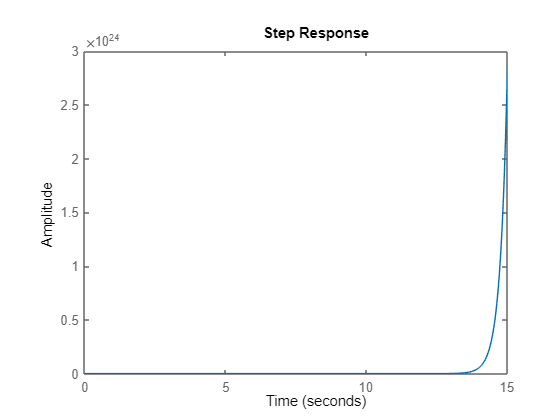

step(gp)

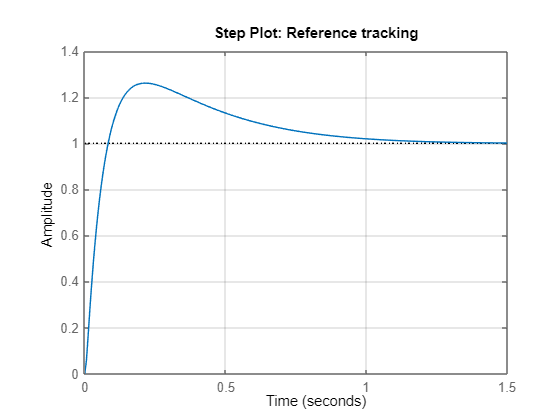

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.0972929;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.440024;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(gp,'PID',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response = getPIDLoopResponse(C2,gp,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response


Kp = C2.Kp;
Ki = C2.ki;
Kd = C2.kd;
N = 1000;

Gc = Kp + Ki*1/s + Kd*(N/(1+N*1/s))

Gc =
 
  7923 s^2 + 4.824e04 s + 7.366e04
  --------------------------------
            s^2 + 1000 s
 
Continuous-time transfer function.



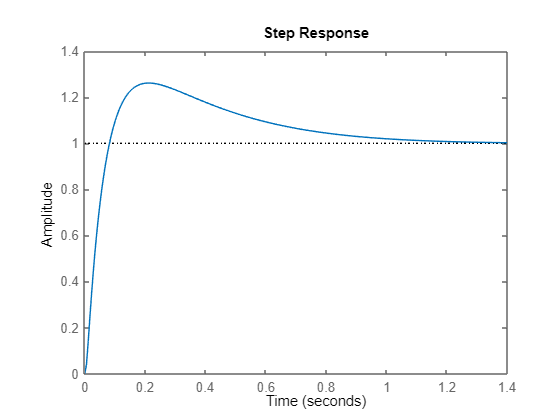

step(feedback(Gc*Gp,1))

stepinfo(feedback(Gc*Gp,1))

ans = struct with fields:
         RiseTime: 0.0585
    TransientTime: 0.9965
     SettlingTime: 0.9965
      SettlingMin: 0.9006
      SettlingMax: 1.2617
        Overshoot: 26.1677
       Undershoot: 0
             Peak: 1.2617
         PeakTime: 0.2140


Part 3

Ts = [ 0.1 0.01 0.001];

Gd_matched_T1 = c2d(Gc, Ts(1), 'matched');
Gd_tustin_T1 = c2d(Gc, Ts(1), 'tustin');
Gd_matched_T2 = c2d(Gc, Ts(2), 'matched');
Gd_tustin_T2 = c2d(Gc, Ts(2), 'tustin');
Gd_matched_T3 = c2d(Gc, Ts(3), 'matched');
Gd_tustin_T3 = c2d(Gc, Ts(3), 'tustin');


Part 4

Gd = Gd_tustin_T2

Gd =
 
  1361 z^2 - 2641 z + 1281
  ------------------------
  z^2 - 0.3333 z - 0.6667
 
Sample time: 0.01 seconds
Discrete-time transfer function.



%stepinfo(out.simout.Data, out.tout)
G = c2d(gp, Ts(2), 'matched')

G =
 
  6.099e-05 z^2 + 0.000122 z + 6.099e-05
  --------------------------------------
   z^3 - 2.082 z^2 + 1.162 z - 0.08193
 
Sample time: 0.01 seconds
Discrete-time transfer function.



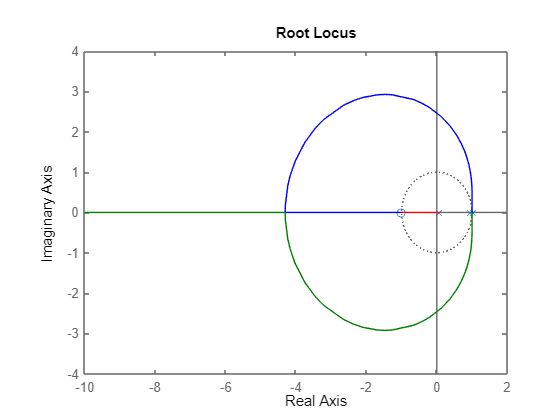

rlocus(G)

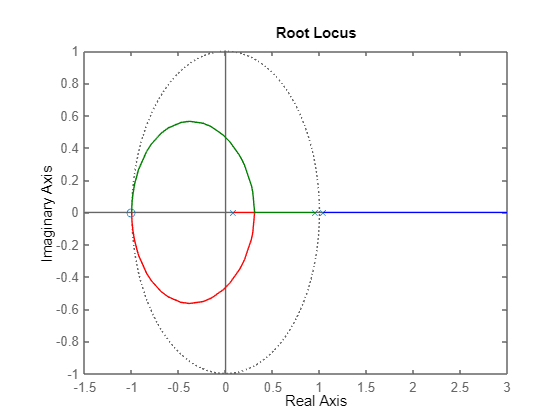

rlocus(-G)

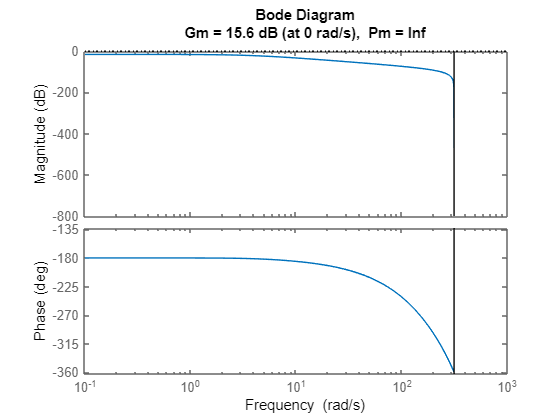

margin(G)

Part 5

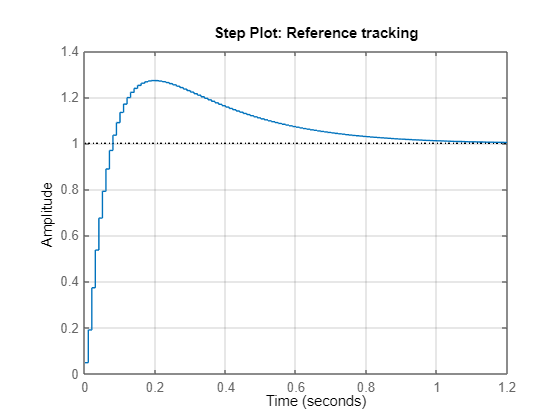

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/0.0972929;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.440024;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2);

% PID tuning algorithm for linear plant model
[C3,pidInfo] = pidtune(G,'PID',wc2,opts2);

% Clear Temporary Variables
clear wc2 PM2 opts2

% Get desired loop response
Response2 = getPIDLoopResponse(C3,G,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response2

Kpd = C3.Kp;
Kid = C3.ki;
Kdd = C3.kd;
N1 = 100;


z = tf(['z'],Ts(2))

z =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gdd = Kpd+Kid*Ts(2)*1/(z-1)+Kdd*N1/(1+N1*Ts(2)/(z-1))

Gdd =
 
  870 z^2 - 1686 z + 817.1
  ------------------------
          z^2 - z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



stepinfo(feedback(Gc*Gp,1))

ans = struct with fields:
         RiseTime: 0.0585
    TransientTime: 0.9965
     SettlingTime: 0.9965
      SettlingMin: 0.9006
      SettlingMax: 1.2617
        Overshoot: 26.1677
       Undershoot: 0
             Peak: 1.2617
         PeakTime: 0.2140


Part 6

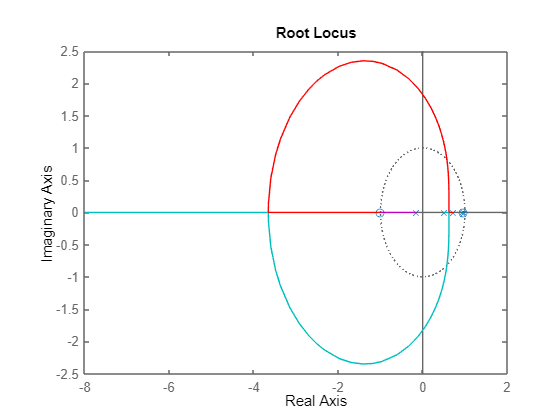

rlocus(feedback(Gdd*G,1))

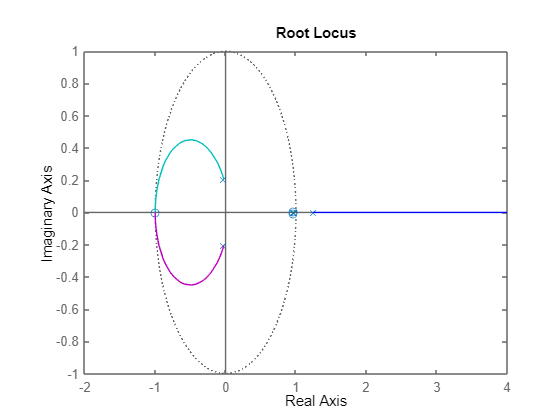

rlocus(feedback(-Gdd*G,1))

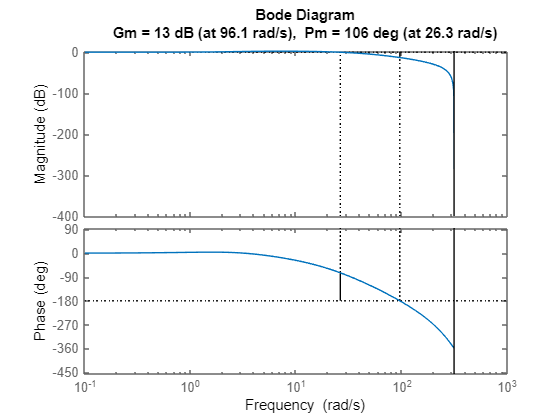

margin(feedback(Gdd*G,1))

part7


Gdiscrete = c2d(tf(num,den),0.01,'zoh');
[Nd, Dd]=tfdata(Gdiscrete);
zpk(Gdiscrete)

ans =
 
  6.5637e-05 (z+2.293) (z+0.1288)
  -------------------------------
  (z-1.04) (z-0.9598) (z-0.08208)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



syms f1 f2 f3

eqns = [ f1+f2+f3==1 , 2.293*f1-f2+f3/2.293==0 , -f1+2.04+f3/1.04==0];
vars = [f1 f2 f3];
f=solve(eqns,vars);

f1 = double(f.f1)

f1 = 0.8455

f2 = double(f.f2)

f2 = 1.3969

f3 = double(f.f3)

f3 = -1.2423

alpha = f3/1.04

alpha = -1.1945

beta1 = f1

beta1 = 0.8455

beta2 = f3/2.293/f1

beta2 = -0.6408

Gdb = 0.8455*((z-0.9598)*(z-0.08208)*(z-0.6408))/((z+0.1288)*(z-1)*(z+1.1945))/6.5e-5

Gdb =
 
     0.8455 z^3 - 1.423 z^2 + 0.6311 z - 0.04268
  -------------------------------------------------
  6.5e-05 z^3 + 2.101e-05 z^2 - 7.601e-05 z - 1e-05
 
Sample time: 0.01 seconds
Discrete-time transfer function.



part 9

%Ts = 0.5;
Ge = expm(Ts(2)*A)

Ge =     1.0008    0.0100    0.0003
    0.1606    0.9990    0.0488
         0         0    0.0821


H = integral(@(t)(expm(t*A)*B),0,Ts(2),'ArrayValued',1)

H =     0.0001
    0.0168
    0.1836


M=[H Ge*H Ge*Ge*H]

M =     0.0001    0.0003    0.0006
    0.0168    0.0258    0.0265
    0.1836    0.0151    0.0012


rank_M = rank(M)

rank_M = 3

N=[C;C*Ge;C*Ge*Ge]

N =     1.0000         0         0
    1.0008    0.0100    0.0003
    1.0032    0.0200    0.0009


rank_N = rank(N)

rank_N = 3

part 10


phi = Ge*Ge*Ge;
K = [0, 0, 1]*inv(M)*phi

K = 1.0e+03 *

    4.1087    0.0741    0.0031


k_follow= (C*(eye(3)-Ge+H*K)^-1*H)^-1;

part 11


phi = Ge*Ge*Ge;
L = phi*inv(N)*[0;0;1]

L =     2.0819
  108.7950
    3.0884


E = Ge-L*C

E =    -1.0811    0.0100    0.0003
 -108.6344    0.9990    0.0488
   -3.0884         0    0.0821
